# iPhone sampling rate conversion for synchronization

## Read recording

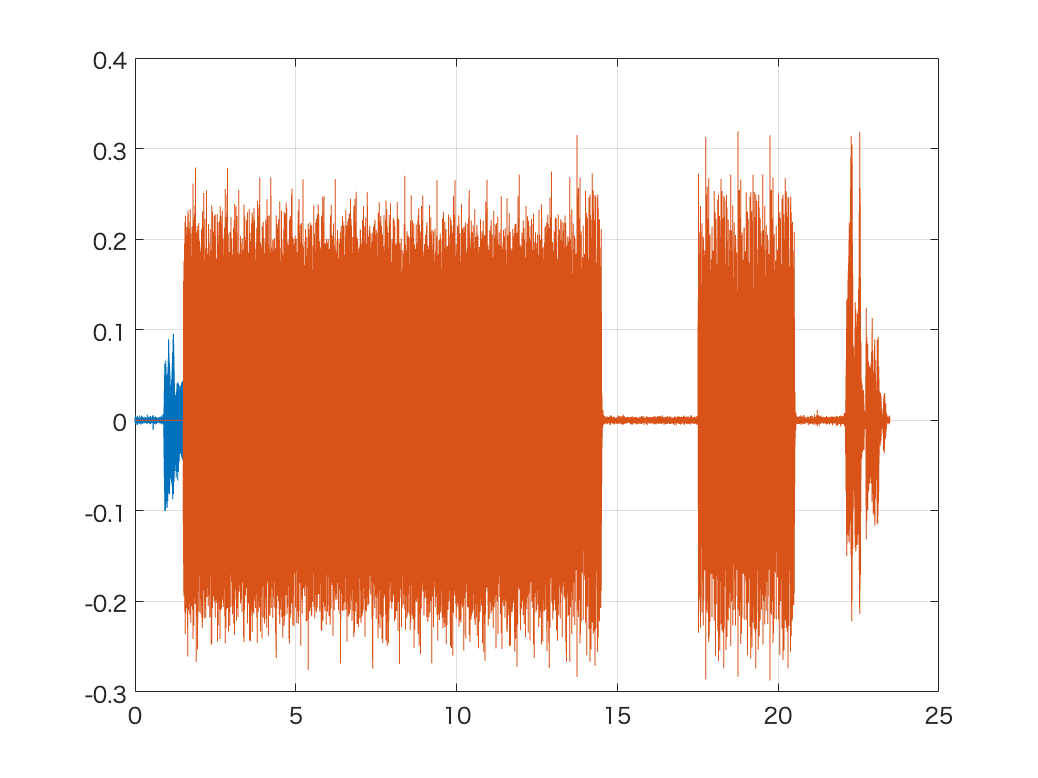

[xMiP, fs] = audioread("compactTestiPhone.wav");
figure;
tt = (1:length(xMiP))'/fs;
plot(tt,xMiP);grid on;
hold all
xMiP(1:72187) = xMiP(1:72187)/10000;
plot(tt,xMiP);grid on;

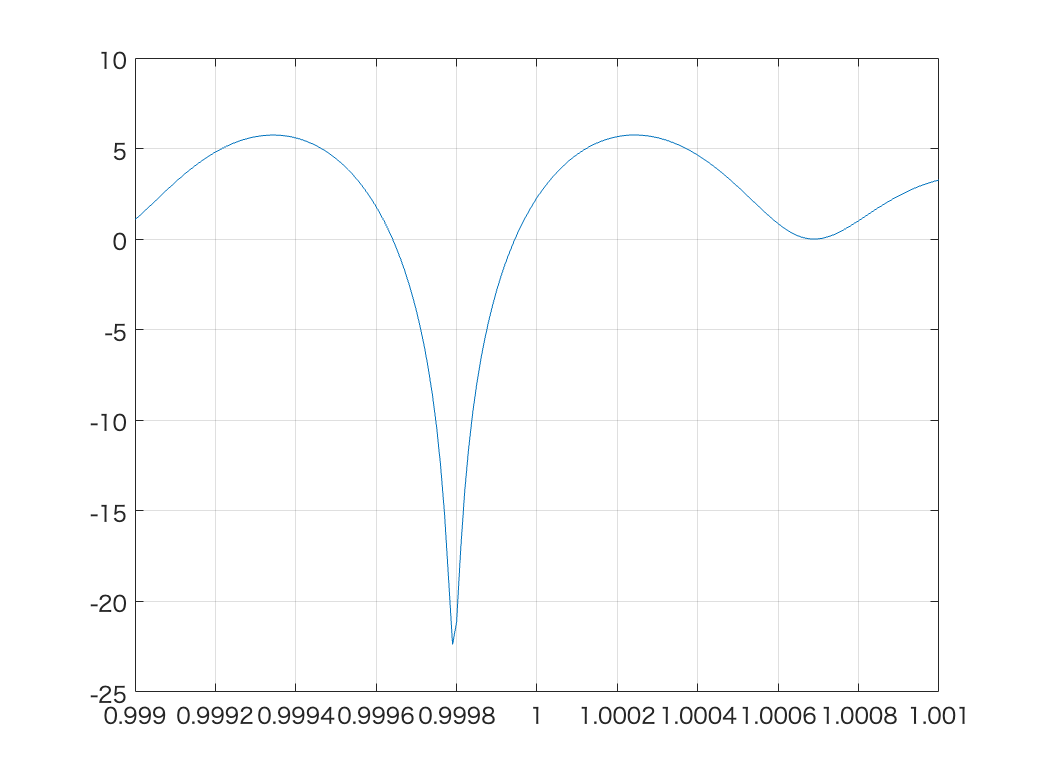

xBaseSeg = xMiP(round(17.5*fs)+(1:2.5*fs));
magList = 0.999:0.00001:1.001;
ttTmp = (1:2*fs)'/fs;
ttBase = (1:length(xBaseSeg))'/fs;
errrList = zeros(length(magList),1);
for ii = 1:length(magList)
    xTmp = interp1(ttBase*magList(ii),xBaseSeg,ttTmp,"linear","extrap");
    errrList(ii) = std(xTmp(1:fs)-xTmp(fs+(1:fs)))/std(xBaseSeg);
end
figure;plot(magList,20*log10(errrList));grid on;

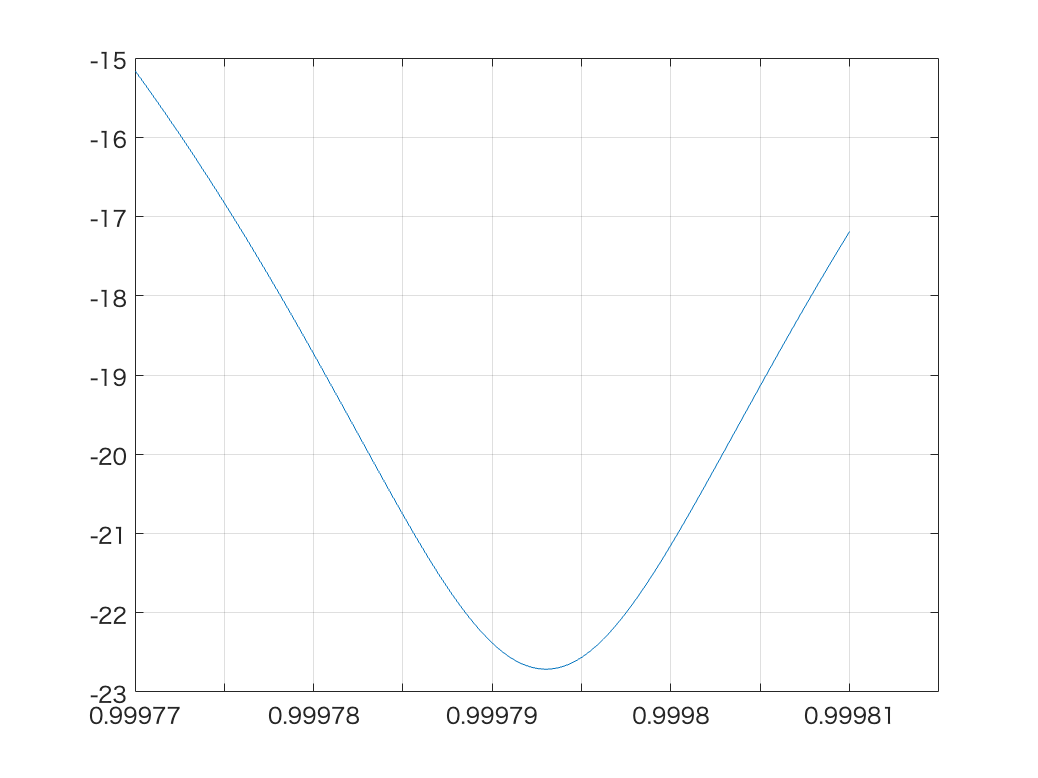

[~,idxMin] = min(errrList);
magListFine = magList(idxMin)+0.00001*(-2:0.01:2);
errrListFine = zeros(length(magListFine),1);
for ii = 1:length(magListFine)
    xTmp = interp1(ttBase*magListFine(ii),xBaseSeg,ttTmp,"linear","extrap");
    errrListFine(ii) = std(xTmp(1:fs)-xTmp(fs+(1:fs)))/std(xBaseSeg);
end
figure;plot(magListFine,20*log10(errrListFine));grid on;

[~,idxMin] = min(magListFine);
magListFine(idxMin)*fs-fs

ans = -11.0400

ttOrg = (1:length(xMiP))'/fs;
xMipFix = interp1(ttOrg*magListFine(idxMin),xMiP,(0:1/fs:ttOrg(end)*magListFine(idxMin))',...
    "linear","extrap");
outtFname = "compactTestiPhoneFix.wav";
audiowrite(outtFname,xMipFix,fs,"BitsPerSample",24);

## Detect reference Position

xPwr = abs(xMiP).^2;
smoothedxPwr = fftfilt(ones(round(fs*0.001),1),xPwr);
onsetThreshold = max(smoothedxPwr)/10^(25/10); % -25 dB
baseIdx = 1:length(smoothedxPwr);
onSet = min(baseIdx(smoothedxPwr>onsetThreshold))

onSet = 72193

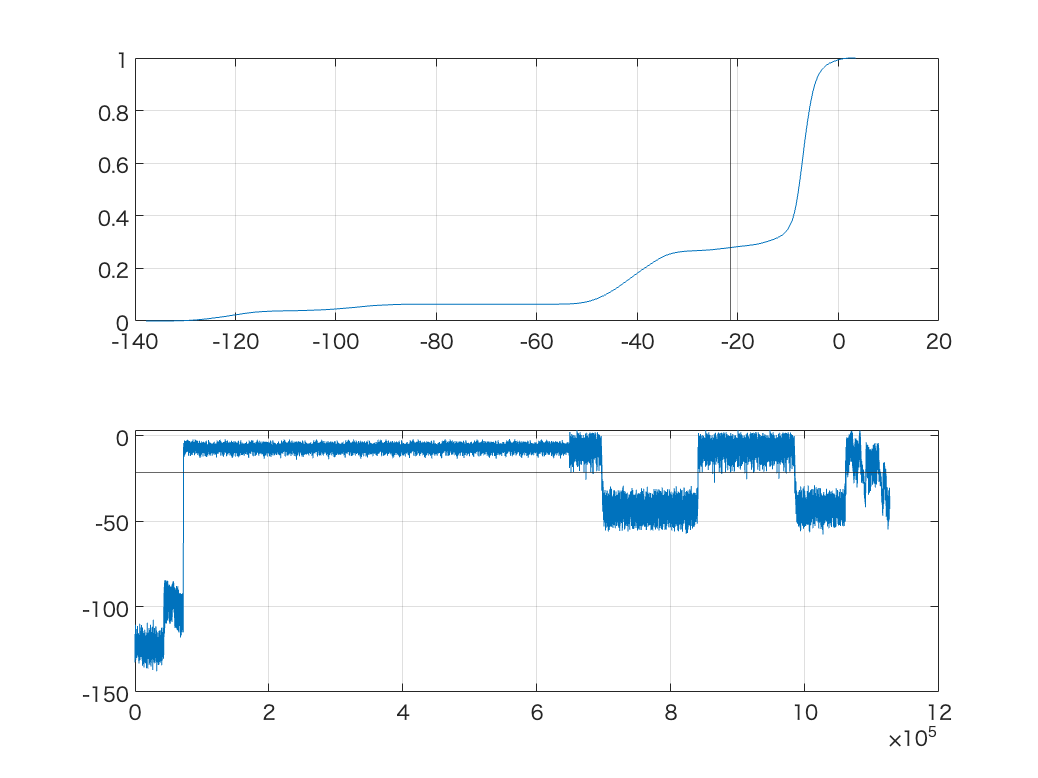


figure;
tiledlayout(2,1);
nexttile
plot(sort(10*log10(smoothedxPwr)),(1:length(smoothedxPwr))/length(smoothedxPwr));grid on;
xline(10*log10(onsetThreshold))
nexttile;
plot(10*log10(smoothedxPwr));grid on;
yline(10*log10(onsetThreshold))

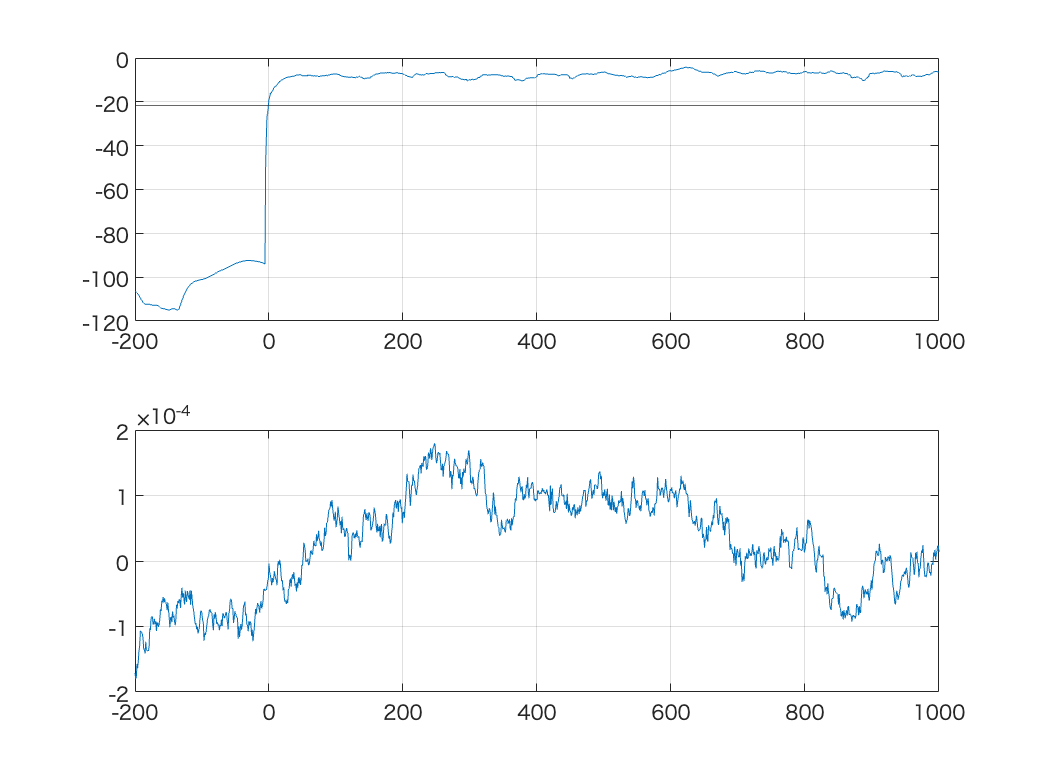

figure;
tiledlayout(2,1);
nexttile
plot(-200:1000,10*log10(smoothedxPwr(onSet+(-200:1000))));grid on;
yline(10*log10(onsetThreshold))
nexttile
plot(-200:1000,xMes(onSet+(-200:1000)));grid on;

## Alignment retry

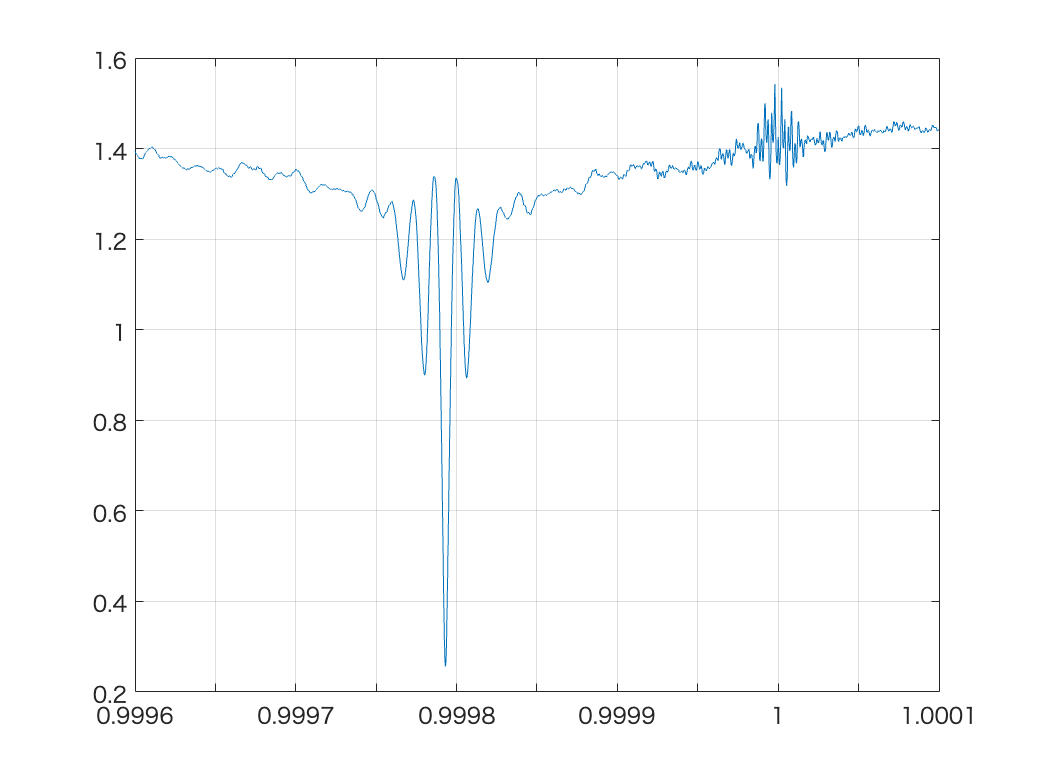

magList = 0.9996:0.0000001:1.0001;
ttSeg = (1:2*fs)'/fs;
ttBase = (1:length(xMiP))'/fs;
errrList = zeros(length(magList),1);
for ii = 1:length(magList)
    ttTmp = (0:1/fs:ttBase(end)*magList(ii))';
    xTmp = interp1(ttBase*magList(ii),xMiP,ttTmp,"linear","extrap");
    iHead = round(72187*magList(ii));
    xSeg1 = xTmp(iHead+fs*2+(1:fs));
    xSeg2 = xTmp(iHead+8*fs+(1:fs));
    errrList(ii) = std(xSeg1+xSeg2)/std(xSeg1);
end
figure;plot(magList,errrList);grid on;

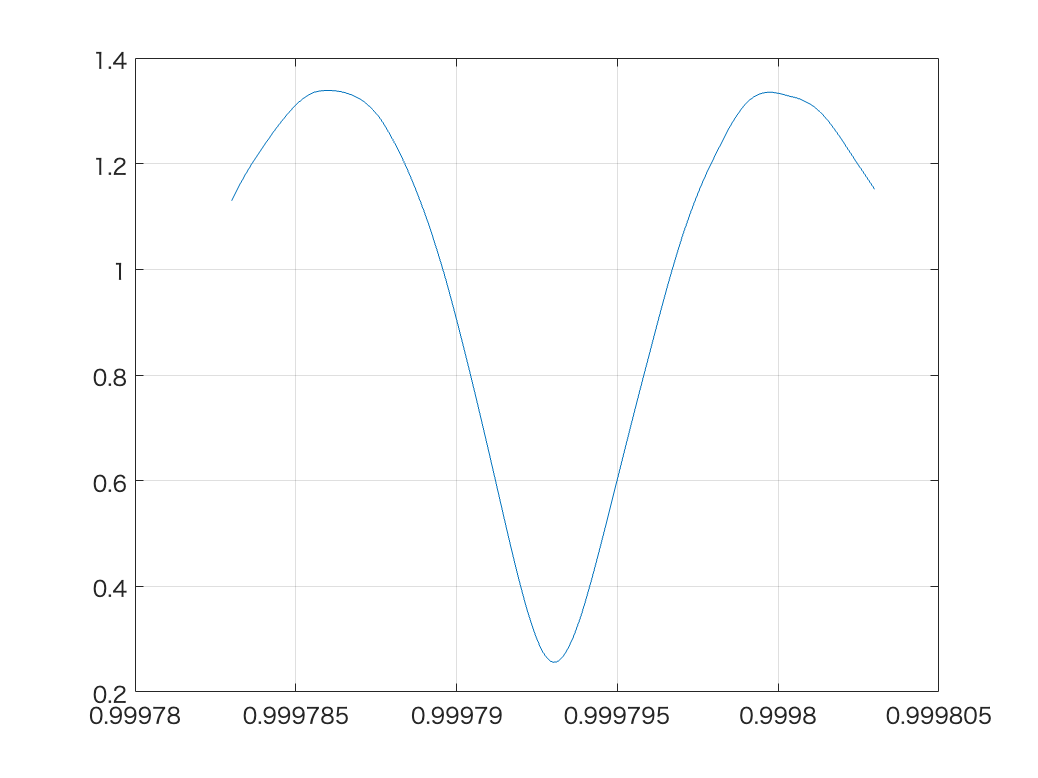

[~,idxMin] = min(errrList);
magListFine = magList(idxMin)+0.0000001*(-100:100);
errrListFine = zeros(length(magListFine),1);
for ii = 1:length(magListFine)
    ttTmp = (0:1/fs:ttBase(end)*magListFine(ii))';
    xTmp = interp1(ttBase*magListFine(ii),xMiP,ttTmp,"linear","extrap");
    iHead = round(72187*magListFine(ii));
    xSeg1 = xTmp(iHead+fs*2+(1:fs));
    xSeg2 = xTmp(iHead+8*fs+(1:fs));
    errrListFine(ii) = std(xSeg1+xSeg2)/std(xSeg1);
end
figure;plot(magListFine,errrListFine);grid on;

[~,idxMin] = min(errrListFine);
magListFine(idxMin)*fs-fs

ans = -9.9360

ttOrg = (1:length(xMiP))'/fs;
xMipFix = interp1(ttOrg*magListFine(idxMin),xMiP,(0:1/fs:ttOrg(end)*magListFine(idxMin))',...
    "linear","extrap");
outtFname = "compactTestiPhoneFix2.wav";
audiowrite(outtFname,xMipFix,fs,"BitsPerSample",24);

## Alignment retry 3rd time

[xMesRaw,fsMes] = audioread("iphoneTest.m4a");
fs = fsMes;
sss = audioinfo("iphoneTest.m4a");
xMiP = xMesRaw(2.54*10^6:3.54*10^6);

nData = length(xMiP);
nData10m3 = round(nData/1000);
lengthRaw = nData + (-nData10m3:nData10m3);
magList = lengthRaw/nData;
%magList = 0.9996:0.0000001:1.0001;
ttSeg = (1:2*fs)'/fs;
ttBase = (1:length(xMiP))'/fs;
errrList = zeros(length(magList),1);
for ii = 1:length(magList)
    ttTmp = (0:1/fs:ttBase(end)*magList(ii))';
    xTmp = interp1(ttBase*magList(ii),xMiP,ttTmp,"linear","extrap");
    iHead = round(72187*magList(ii));
    xSeg1 = xTmp(iHead+fs*2+(1:fs));
    xSeg2 = xTmp(iHead+8*fs+(1:fs));
    errrList(ii) = std(xSeg1+xSeg2)/std(xSeg1);
end

[~,idxMin] = min(errrList);
nDataFix = nData*magList(idxMin);
magListFine = (nDataFix+(-20:1/10:20))/nData;
%magListFine = magList(idxMin)+0.0000001*(-100:100);
errrListFine = zeros(length(magListFine),1);
for ii = 1:length(magListFine)
    ttTmp = (0:1/fs:ttBase(end)*magListFine(ii))';
    xTmp = interp1(ttBase*magListFine(ii),xMiP,ttTmp,"linear","extrap");
    iHead = round(72187*magListFine(ii));
    xSeg1 = xTmp(iHead+fs*2+(1:fs));
    xSeg2 = xTmp(iHead+8*fs+(1:fs));
    errrListFine(ii) = std(xSeg1+xSeg2)/std(xSeg1);
end

[~,idxMin2] = min(errrListFine);
magListFine(idxMin2)*fs-fs

ans = -9.9456

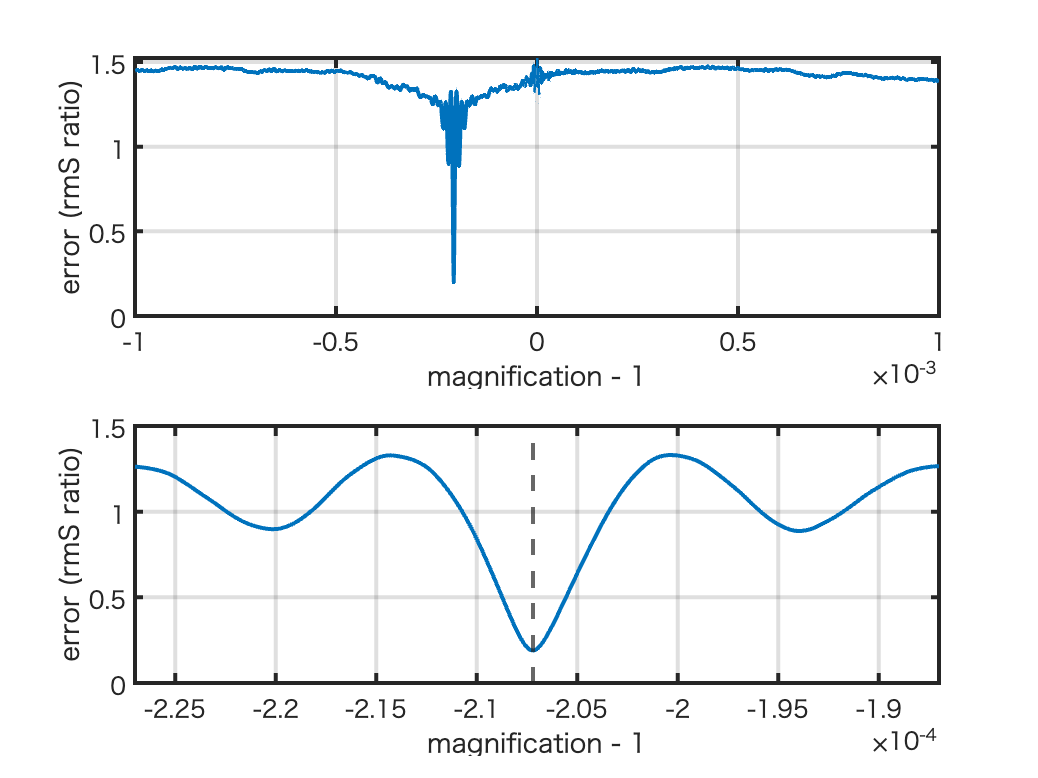

figure;
tiledlayout(2,1)
nexttile
plot(magList-1,errrList,"LineWidth",2);grid on;
set(gca,"LineWidth",2,"fontsize",12)
xlabel("magnification - 1")
ylabel("error (rmS ratio)")
%figure;
nexttile;
plot(magListFine-1,errrListFine,"LineWidth",2);grid on;
set(gca,"LineWidth",2,"fontsize",12)
axis([[magListFine(1) magListFine(end)]-1 0 1.5])
xline(magListFine(idxMin2)-1,"--","LineWidth",2)
xlabel("magnification - 1")
ylabel("error (rmS ratio)")
%print -deps iphoneAlignTest.eps

ttOrg = (1:length(xMiP))'/fs;
xMipFix = interp1(ttOrg*magListFine(idxMin2),xMiP,(0:1/fs:ttOrg(end)*magListFine(idxMin2))',...
    "linear","extrap");
%outtFname = "compactTestiPhoneFix3.wav";
%audiowrite(outtFname,xMipFix,fs,"BitsPerSample",24);
